## Fuel economy

awesome analysis


$$\sqrt{42}$$


importing data

carData=importfile('2004dat.xlsx');

plotting data

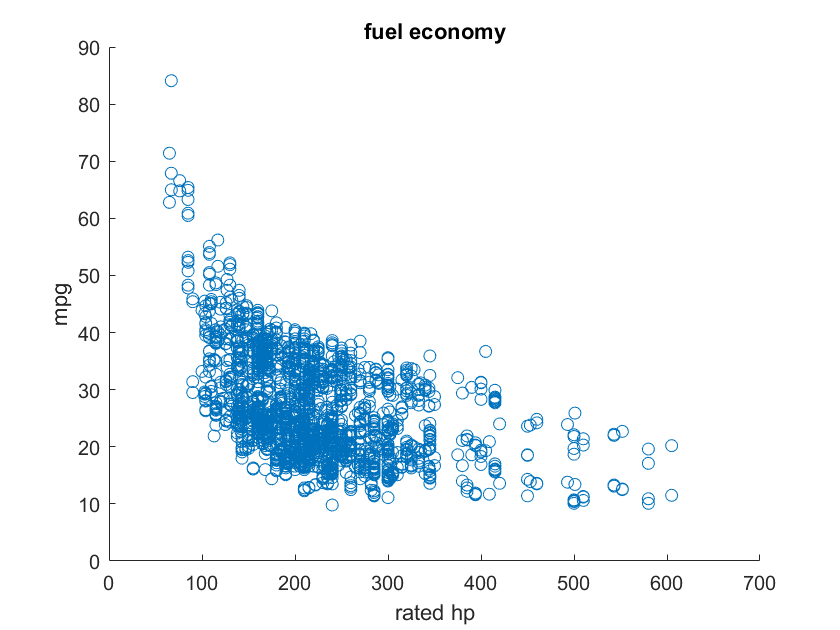

%plot(carData.RatedHP,carData.MPG)
%scatter(carData.RatedHP,carData.MPG)
createfigure(carData.RatedHP,carData.MPG)

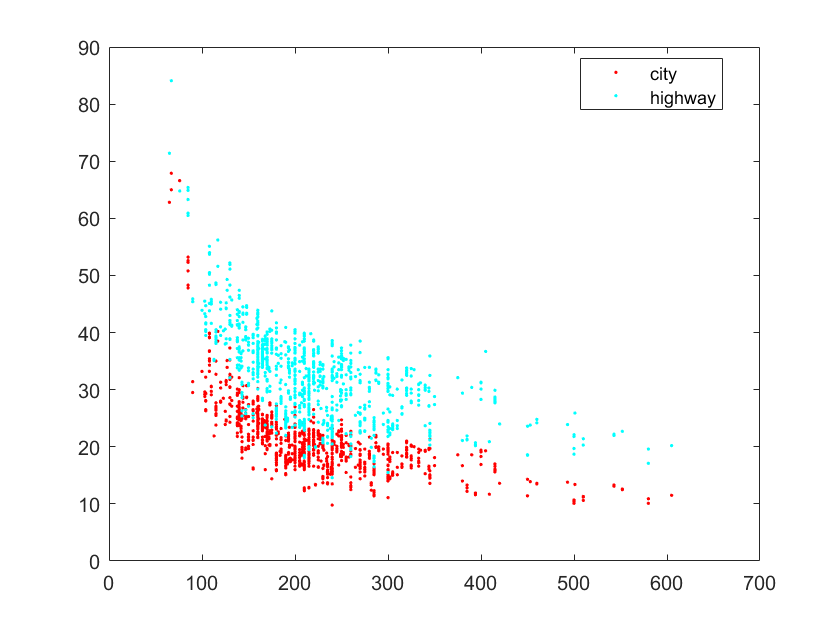

figure
gscatter(carData.RatedHP,carData.MPG,carData.City_Highway)

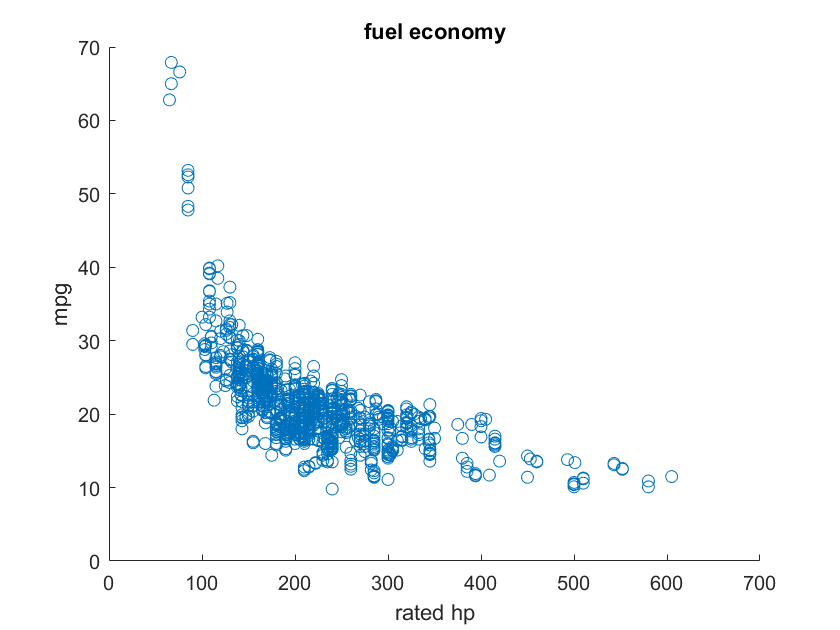

carcity= carData.City_Highway == 'city';
citympg=carData.MPG(carcity);
cityhp=carData.RatedHP(carcity);
createfigure(cityhp,citympg)

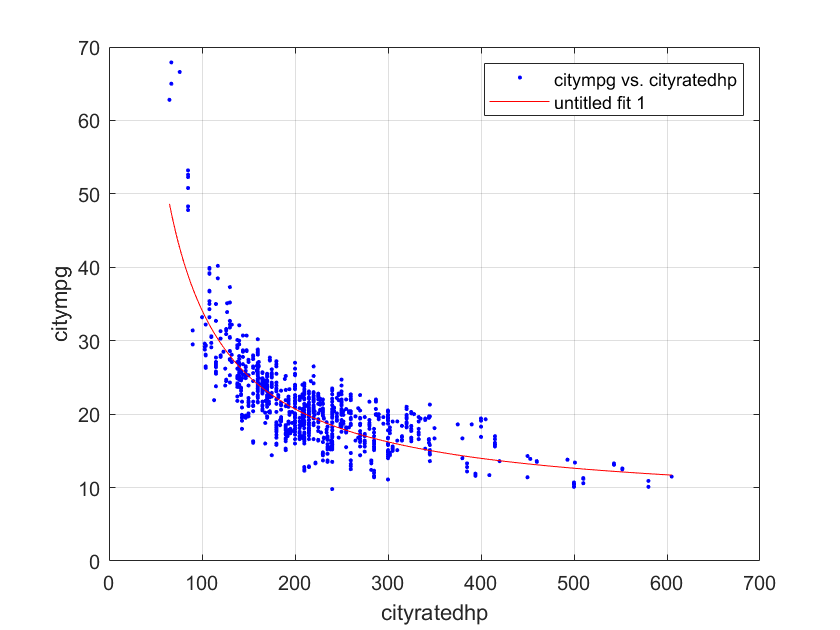

model =      General model:
     model(x) = b1+b2/x
     Coefficients (with 95% confidence bounds):
       b1 =       7.253  (6.658, 7.848)
       b2 =        2690  (2581, 2800)

model=createFit(cityhp,citympg)

model(600)

ans = 11.7371